# Multi-Period Distributed Optimal Power Flow

## Temporally Brute-Forced, Spatially Distributed, Integer-Relaxed NLP.

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep) )
    addpath(genpath('functions\'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "loss_min"

objFunction = "loss_min"

numAreas = 4

numAreas = 4

T = 2

T = 2

macroItrMax = 10; % Max no. of permissible iterations for optimizing an area
noBatteries = false;
alpha = 1e-5;
% gamma = 1e-1;
gamma = 1e0;

displayTables = true;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;
saveSCDPlots = true;


delta_t = 0.25; % 15 minutes = 0.25 hours
globalPVCoeff = 2.3;
% globalPVCoeff = 1.0;
% lambdaVals = generateLoadProfile(T, 1.0, 1.1, 'upwards')
lambdaVals = generateLoadProfile(T, 1.0, 1.4, 'upwards')

lambdaVals =     1.0000    1.4000


% lambdaVals = generateLoadProfile(T, 1.0, 1.0, 'upwards')
loadVals = lambdaVals*3

loadVals =     3.0000    4.2000


pvCoeffVals = globalPVCoeff*generatePVProfile(T, 0.8, 1.2, 0.9)

pvCoeffVals =     2.7600    2.0700


% pvCoeffVals = globalPVCoeff*generatePVProfile(T, 1.0, 1.0, 1.0)

if numAreas == 1
    copf = true;
    myfprintf(verbose, logging, "Centralized OPF it is.");
    simNatureString = "Centralized-OPF";
else
    copf = false;
    myfprintf(verbose, logging, "Perforiming Distributed OPF with %d Areas.", numAreas);
    simNatureString = "Spatially-Distributed-OPF";
end


if strcmp(systemName, "ieee123")
    N = 128;
    m = N-1;
else
    error("Unknown Power System")
end

% actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
% N = max(actualBusNums);

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
else
    error("Objective Function NOT recognized.")
end

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

sysInfo = struct();
sysInfo.N = N;
sysInfo.m = m;
sysInfo.numAreas = numAreas;
sysInfo.numChildAreas = numChildAreas; % An array of containing no. of 
% child areas for each area
sysInfo.systemName = systemName;
sysInfo.isLeaf = isLeaf;
sysInfo.isRoot = isRoot;
sysInfo.kVA_B = kVA_B;
sysInfo.kV_B = kV_B;
sysInfo.Battery.chargeToPowerRatio = chargeToPowerRatio;
sysInfo.CBTable = CBTable;
PLoss_allT_vs_macroItr = zeros(macroItrMax, 1);
PLoss_1toT_vs_macroItr = zeros(T, macroItrMax);
sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
sysInfo.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
simInfo = struct();
simInfo.copf = copf;
simInfo.simNatureString = simNatureString;
simInfo.alpha = alpha;
simInfo.gamma = gamma;
simInfo.lambdaVals = lambdaVals;
simInfo.pvCoeffVals = pvCoeffVals;
simInfo.noBatteries = noBatteries;
simInfo.objFunction = objFunction;
simInfo.T = T;
if copf
    simInfo.alg.spatial = "CentralizedOPF";
else
    simInfo.alg.spatial = "ENApp";
end
simInfo.alg.temporal = "BruteForce";
simInfo.alg.macroItrMax = macroItrMax;
% stopping criterion
macroItrResidualTolerance = 0.001 ; % Tolerance

simInfo.alg.macroItrResidualTolerance = macroItrResidualTolerance;
simInfo.macroItrsCompleted = 0;
simInfo.alg.correctionStep = a;
simInfo.macroItr = 0;

simInfo.alg.microItrMax = 100;
simInfo.alg.tolfun = 1e-6;
simInfo.alg.stepTol = 1e-6;
simInfo.alg.constraintTol = 1e-6;
simInfo.alg.optimalityTol = 1e-6;

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);


#### Start with the algorithm

if logging && verbose
    error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
elseif logging && ~verbose
    fileOpenedFlag = true;
    fid = fopen(saveLocationFilename, 'w');
elseif ~logging
    logging = verbose;
    fid = 1;
else
    fid = 1;
end

myfprintf(true, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
"will be run.\n", T, delta_t*60, delta_t*T);

myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
keepRunningIterations = true;
time_dist = zeros(macroItrMax, numAreas);

maxResidual_vs_macroItr_allT = zeros(macroItrMax, 1);
v1_1 = 1.03^2*ones(numAreas, 1);
v1_1toT = repmat(v1_1, 1, T);

Se_iter = zeros(macroItrMax, numAreas, T);
% Se_iter = zeros(macroItrMax, m, numAreas, T);
V_iter = zeros(macroItrMax, N, numUniqueParents, T);
S12_allRelationships = CBTable.S_childArea;
S12_allRelationships_1toT = repmat(S12_allRelationships, 1, T);
S_parent_1toT = zeros(numAreas, T);
S_Areas_1toT = zeros(N, numAreas, T);
v_Areas_1toT = zeros(N, numAreas, T);
% v1_1toT_vs_macroItr = zeros(numAreas, T, macroItrMax);
v1_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
S12_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);

while keepRunningIterations
    % for Area = 1:numAreas
    % for Area = 1
    for Area = [2 3 1 4]
        macroItr = simInfo.macroItr;
        myfprintf(true, "Macro-iteration %d: Running OPF for Area %d.\n", macroItr+1, Area);

        v_parAr_1toT = v1_1toT(Area, 1:T)
        S_chArs_1toT = S12_allRelationships_1toT(CBTable.parentArea == Area, 1:T)

        if macroItr == 0
            areaInfo.Area = Area;
        else
            areaInfo = sysInfo.Area{Area};
        end

        [xVals_Area, sysInfo, simInfo, ...
            time_dist] = ...
            ...
            NL_OPF_dist2(sysInfo, simInfo, areaInfo, v_parAr_1toT, S_chArs_1toT, ...
            lambdaVals, pvCoeffVals, time_dist, 'verbose', verbose, 'saveToFile', true, 'logging', logging, ...
            'saveSCDPlots', saveSCDPlots);
        
        nVars1_Area = length(xVals_Area)/T;
        xVals_Area_1toT = reshape(xVals_Area, nVars1_Area, T)
        % macroItr = simInfo.macroItr;
        
        myfprintf(true, fid, "Current Macro-iteration %d: OPF for Area %d computed.\n", macroItr+1, Area)
        areaInfo = sysInfo.Area{Area};
        N_Area = areaInfo.N_Area;
        m_Area = areaInfo.m_Area;
    
        % indices_Pij = areaInfo.indices_Pij;
        P_Area_1toT = xVals_Area(areaInfo.indices_Pij)'; %m_Areax1
        Q_Area_1toT = xVals_Area(areaInfo.indices_Qij)'; %m_Areax1
        S_Area_1toT = complex(P_Area_1toT, Q_Area_1toT); %m_Areax1
        vAll_Area_1toT = xVals_Area(areaInfo.indices_vAllj)'; %N_Areax1
        
        S_parent_1toT(Area, 1:T) = S_Area_1toT(1, 1:T);

        v_Areas_1toT(1:N_Area, Area, 1:T) = vAll_Area_1toT;
        S_Areas_1toT(1:m_Area, Area, 1:T) = S_Area_1toT;  % Storing all the S flow of the Area
        
        PLoss_allT_vs_macroItr(macroItr+1) = PLoss_allT_vs_macroItr(macroItr+1) + areaInfo.PLoss_allT;
        PLoss_1toT_vs_macroItr(1:T, macroItr+1) = PLoss_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PLoss_1toT;
        sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;  
        sysInfo.Ploss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
        % keyboard
    end
    
    myfprintf(true, "Macro-iteration %d: OPF's for all Areas completed. Checking for convergence.\n", macroItr+1);
    % first let's quickly compute system losses for the macroItr first and
    % store them
    
    if ~copf
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            myfprintf(true, "Checking for convergence between parent Area %d and child Area %d\n", parAr, chAr);

            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            S12_fromParent_1toT = reshape(S_Areas_1toT(parentAreaConnectingBus - 1, parAr, 1:T), 1, T)
            S12_intoChild_1toT = reshape(S_parent_1toT(chAr, 1:T), 1, T)
    
            delta_S12_1toT = S12_fromParent_1toT - S12_intoChild_1toT
    
            v_parentSide_1toT = reshape(v_Areas_1toT(parentAreaConnectingBus, parAr, 1:T), 1, T);
            v_childSide_1toT = v1_1toT(chAr, 1:T);
    
            v1_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = v_parentSide_1toT;
            S12_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = S12_intoChild_1toT;

            delta_v_1toT = v_parentSide_1toT - v_childSide_1toT
    
            Residual_Area_1toT = reshape([delta_S12_1toT; delta_v_1toT], 2*T, 1);
            
            [currentMaxResidual_1toT, lin_idx] = max(abs(Residual_Area_1toT));

            row = lin_idx;
            myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at index %d.\n", macroItr+1, currentMaxResidual_1toT, row);

            
            if currentMaxResidual_1toT > maxResidual_vs_macroItr_allT(macroItr+1)
                maxResidual_vs_macroItr_allT(macroItr+1) = currentMaxResidual_1toT;
                myfprintf(true, "It is even bigger than the previous biggest residual.\n");
            end
    
        end
        
        myfprintf(true, "Macro-iteration %d: Checking for convergence among all connected areas completed.\n", macroItr+1);
        if macroItr == macroItrMax - 1
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif currentMaxResidual_1toT < macroItrResidualTolerance
            myfprintf(true, "MPOPF for Horizon T = %d Converged in %d macro-iterations!\n", T, macroItr+1);
            keepRunningIterations = false;
            maxResidual_vs_macroItr_allT = maxResidual_vs_macroItr_allT(1:macroItr+1);
    
        else
            myfprintf(true, "MPOPF for Horizon T = %d , Still yet to converge after %d macro-iterations, continuing.\n", T, macroItr+1)
            %Communication-
            myfprintf(true, "Since there is still a difference in boundary variables, " + ...
                "let's exchange boundary variables.\n")

            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                myfprintf(true, "Communicating between parent Area %d and child Area %d\n", parAr, chAr);

                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);

                areaInfo_par = sysInfo.Area{parAr};
                areaInfo_ch = sysInfo.Area{chAr};
    
                
                V_iter(macroItr+1, busParTo, parAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T) ;

                Se_iter(macroItr+1, chAr, 1:T) = S_parent_1toT(chAr, 1:T);
    
                if macroItr >= 2
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = a(2)*reshape(V_iter(macroItr-1, busParTo, parAr, 1:T), 1, T) + ...
                        a(1)*reshape(V_iter(macroItr, busParTo, parAr, 1:T), 1, T) + ...
                        (1-sum(a))*reshape(v_Areas_1toT(busParTo, parAr, 1:T), 1, T)
                    disp(v1_1toT(char, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)

                    S12_allRelationships_1toT(relationshipNum, 1:T) = a(2)*reshape(Se_iter(macroItr-1, chAr, 1:T), 1, T)+...
                        a(1)*reshape(Se_iter(macroItr, chAr, 1:T), 1, T)+...
                        (1-sum(a))*S_parent_1toT(chAr, 1:T);
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));
                else
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T)
                    disp(v1_1toT(chAr, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)
                    S12_allRelationships_1toT(relationshipNum, 1:T) = S_parent_1toT(chAr, 1:T)
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));

    
                end
    
            end

            simInfo.macroItr = macroItr + 1;

        end

        
    else
        keepRunningIterations = false;
        myfprintf(verbose, "Centralized MPOPF for %d Horizons ended.\n", T);
    end

end

Macro-iteration 1: Running OPF for Area 2.


v_parAr_1toT =     1.0609    1.0609


S_chArs_1toT =      0     0


xVals_Area_1toT =     0.0261    0.0290
    0.0261    0.0290
    0.0222    0.0247
    0.0188    0.0206
    0.0019    0.0022
    0.0009    0.0011
    0.0169    0.0184
    0.0009    0.0012
    0.0005    0.0005
    0.0159    0.0172


Macro-iteration 1: Running OPF for Area 3.


v_parAr_1toT =     1.0609    1.0609



S_chArs_1toT =

  0×2 empty double matrix



xVals_Area_1toT =     0.0467    0.0521
    0.0467    0.0521
    0.0042    0.0047
    0.0029    0.0032
    0.0013    0.0015
    0.0007    0.0006
    0.0401    0.0429
    0.0002    0.0003
    0.0399    0.0426
    0.0015    0.0019


Macro-iteration 1: Running OPF for Area 1.


v_parAr_1toT =     1.0609    1.0609


S_chArs_1toT =      0     0
     0     0


xVals_Area_1toT =     0.0324    0.0361
    0.0324    0.0361
    0.0013    0.0014
    0.0062    0.0068
    0.0030    0.0033
    0.0032    0.0035
    0.0026    0.0029
    0.0214    0.0236
    0.0205    0.0227
    0.0051    0.0056


Macro-iteration 1: Running OPF for Area 4.


v_parAr_1toT =     1.0609    1.0609



S_chArs_1toT =

  0×2 empty double matrix



xVals_Area_1toT =     0.0612    0.0681
    0.0612    0.0681
    0.0612    0.0681
    0.0046    0.0051
    0.0042    0.0047
    0.0020    0.0019
    0.0018    0.0024
    0.0394    0.0439
    0.0046    0.0051
    0.0028    0.0031


Macro-iteration 1: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 1.0e-20 *

   0.0496 - 0.1120i   0.0369 + 0.0785i


S12_intoChild_1toT =    0.0261 - 0.0000i   0.0290 - 0.0000i


delta_S12_1toT =   -0.0261 + 0.0000i  -0.0290 + 0.0000i


delta_v_1toT = 1.0e-03 *

   -0.5896   -0.6317


Macro-iteration 1: Current Biggest Residual is 2.901477e-02 at index 3.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 1.0e-20 *

  -0.0736 - 0.0661i  -0.0758 - 0.2518i


S12_intoChild_1toT =    0.0467 - 0.0002i   0.0521 + 0.0124i


delta_S12_1toT =   -0.0467 + 0.0002i  -0.0521 - 0.0124i


delta_v_1toT = 1.0e-03 *

   -0.7650   -0.8244


Macro-iteration 1: Current Biggest Residual is 5.355962e-02 at index 3.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 1.0e-21 *

   0.0288 + 0.4163i  -0.1234 - 0.8427i


S12_intoChild_1toT =    0.0612 - 0.0011i   0.0681 - 0.0008i


delta_S12_1toT =   -0.0612 + 0.0011i  -0.0681 + 0.0008i


delta_v_1toT = 1.0e-03 *

   -0.7039   -0.7712


Macro-iteration 1: Current Biggest Residual is 6.807564e-02 at index 3.


It is even bigger than the previous biggest residual.


Macro-iteration 1: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 2 , Still yet to converge after 1 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609    1.0609
    1.0603    1.0603
    1.0609    1.0609
    1.0609    1.0609


    1.0603    1.0603



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.0261 - 0.0000i   0.0290 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i


   0.0261 - 0.0000i   0.0290 - 0.0000i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609    1.0609
    1.0603    1.0603
    1.0601    1.0601
    1.0609    1.0609


    1.0601    1.0601



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.0261 - 0.0000i   0.0290 - 0.0000i
   0.0467 - 0.0002i   0.0521 + 0.0124i
   0.0000 + 0.0000i   0.0000 + 0.0000i


   0.0467 - 0.0002i   0.0521 + 0.0124i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609    1.0609
    1.0603    1.0603
    1.0601    1.0601
    1.0602    1.0601


    1.0602    1.0601



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.0261 - 0.0000i   0.0290 - 0.0000i
   0.0467 - 0.0002i   0.0521 + 0.0124i
   0.0612 - 0.0011i   0.0681 - 0.0008i


   0.0612 - 0.0011i   0.0681 - 0.0008i



Macro-iteration 2: Running OPF for Area 2.


v_parAr_1toT =     1.0603    1.0603


S_chArs_1toT =    0.0612 - 0.0011i   0.0681 - 0.0008i


xVals_Area_1toT =     0.0592    0.0657
    0.0592    0.0657
    0.0564    0.0623
    0.0560    0.0586
    0.0005   -0.0033
    0.0002   -0.0016
    0.0555    0.0619
   -0.0026   -0.0039
   -0.0012   -0.0019
    0.0581    0.0658


Macro-iteration 2: Running OPF for Area 3.


v_parAr_1toT =     1.0601    1.0601



S_chArs_1toT =

  0×2 empty double matrix



xVals_Area_1toT =     0.0467    0.0521
    0.0467    0.0521
    0.0041    0.0047
    0.0028    0.0032
    0.0013    0.0015
    0.0007    0.0007
    0.0401    0.0429
    0.0002    0.0003
    0.0398    0.0425
    0.0015    0.0019


Macro-iteration 2: Running OPF for Area 1.


v_parAr_1toT =     1.0609    1.0609


S_chArs_1toT =    0.0261 - 0.0000i   0.0290 - 0.0000i
   0.0467 - 0.0002i   0.0521 + 0.0124i


xVals_Area_1toT =     0.0620    0.0671
    0.0620    0.0671
    0.0002    0.0007
    0.0042    0.0050
    0.0021    0.0028
    0.0021    0.0022
    0.0019    0.0025
    0.0571    0.0561
    0.0569    0.0575
    0.0003    0.0006


Macro-iteration 2: Running OPF for Area 4.


v_parAr_1toT =     1.0602    1.0601



S_chArs_1toT =

  0×2 empty double matrix



xVals_Area_1toT =     0.0612    0.0680
    0.0612    0.0680
    0.0612    0.0680
    0.0046    0.0051
    0.0042    0.0047
    0.0020    0.0019
    0.0018    0.0024
    0.0393    0.0439
    0.0046    0.0051
    0.0028    0.0031


Macro-iteration 2: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT =    0.0261 - 0.0000i   0.0290 - 0.0000i


S12_intoChild_1toT =    0.0592 - 0.0001i   0.0657 - 0.0001i


delta_S12_1toT =   -0.0331 + 0.0001i  -0.0367 + 0.0001i


delta_v_1toT = 1.0e-03 *

   -0.7378   -0.7990


Macro-iteration 2: Current Biggest Residual is 3.665254e-02 at index 3.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT =    0.0467 - 0.0002i   0.0521 + 0.0124i


S12_intoChild_1toT =    0.0467 - 0.0002i   0.0521 + 0.0124i


delta_S12_1toT = 1.0e-04 *

   0.3107 - 0.3326i   0.1184 + 0.2107i


delta_v_1toT =    -0.0011   -0.0013


Macro-iteration 2: Current Biggest Residual is 1.290588e-03 at index 4.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT =    0.0612 - 0.0011i   0.0681 - 0.0008i


S12_intoChild_1toT = 1×2
   0.0612 - 0.0011i   0.0680 - 0.0008i


delta_S12_1toT = 1×2
1.0e-04 *

   0.1679 - 0.0268i   0.3001 + 0.0618i


delta_v_1toT = 1×2
   -0.0020   -0.0022


Macro-iteration 2: Current Biggest Residual is 2.210038e-03 at index 4.


Macro-iteration 2: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 2 , Still yet to converge after 2 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 2 Communication Voltage:****


v1_1toT = 4×2
    1.0609    1.0609
    1.0596    1.0595
    1.0601    1.0601
    1.0602    1.0601


    1.0596    1.0595



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT = 3×2
   0.0592 - 0.0001i   0.0657 - 0.0001i
   0.0467 - 0.0002i   0.0521 + 0.0124i
   0.0612 - 0.0011i   0.0681 - 0.0008i


   0.0592 - 0.0001i   0.0657 - 0.0001i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 2 Communication Voltage:****


v1_1toT = 4×2
    1.0609    1.0609
    1.0596    1.0595
    1.0590    1.0588
    1.0602    1.0601


    1.0590    1.0588



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT = 3×2
   0.0592 - 0.0001i   0.0657 - 0.0001i
   0.0467 - 0.0002i   0.0521 + 0.0124i
   0.0612 - 0.0011i   0.0681 - 0.0008i


   0.0467 - 0.0002i   0.0521 + 0.0124i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 2 Communication Voltage:****


v1_1toT = 4×2
    1.0609    1.0609
    1.0596    1.0595
    1.0590    1.0588
    1.0582    1.0579


    1.0582    1.0579



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT = 3×2
   0.0592 - 0.0001i   0.0657 - 0.0001i
   0.0467 - 0.0002i   0.0521 + 0.0124i
   0.0612 - 0.0011i   0.0680 - 0.0008i


   0.0612 - 0.0011i   0.0680 - 0.0008i



Macro-iteration 3: Running OPF for Area 2.


v_parAr_1toT = 1×2
    1.0596    1.0595


S_chArs_1toT = 1×2
   0.0612 - 0.0011i   0.0680 - 0.0008i


xVals_Area_1toT = 133×2
    0.0592    0.0656
    0.0592    0.0656
    0.0564    0.0623
    0.0559    0.0586
    0.0005   -0.0033
    0.0002   -0.0016
    0.0555    0.0619
   -0.0026   -0.0039
   -0.0012   -0.0019
    0.0580    0.0658


Macro-iteration 3: Running OPF for Area 3.


v_parAr_1toT = 1×2
    1.0590    1.0588



S_chArs_1toT =

  0×2 empty double matrix



xVals_Area_1toT = 147×2
    0.0467    0.0520
    0.0467    0.0520
    0.0042    0.0047
    0.0029    0.0032
    0.0013    0.0015
    0.0007    0.0007
    0.0401    0.0428
    0.0002    0.0003
    0.0398    0.0425
    0.0015    0.0019


Macro-iteration 3: Running OPF for Area 1.


v_parAr_1toT = 1×2
    1.0609    1.0609


S_chArs_1toT = 2×2
   0.0592 - 0.0001i   0.0657 - 0.0001i
   0.0467 - 0.0002i   0.0521 + 0.0124i


xVals_Area_1toT = 276×2
    0.0789    0.0843
    0.0789    0.0843
    0.0002   -0.0001
    0.0031    0.0039
    0.0015    0.0025
    0.0015    0.0014
    0.0013    0.0024
    0.0751    0.0760
    0.0758    0.0780
   -0.0014   -0.0029


Macro-iteration 3: Running OPF for Area 4.


v_parAr_1toT = 1×2
    1.0582    1.0579



S_chArs_1toT =

  0×2 empty double matrix



xVals_Area_1toT = 393×2
    0.0611    0.0680
    0.0611    0.0680
    0.0611    0.0680
    0.0046    0.0051
    0.0042    0.0047
    0.0020    0.0019
    0.0018    0.0024
    0.0393    0.0439
    0.0046    0.0051
    0.0028    0.0031


Macro-iteration 3: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 1×2
   0.0592 - 0.0001i   0.0657 - 0.0001i


S12_intoChild_1toT = 1×2
   0.0592 - 0.0001i   0.0656 - 0.0001i


delta_S12_1toT = 1×2
1.0e-04 *

   0.3268 + 0.0242i   0.3445 + 0.0287i


delta_v_1toT = 1×2
1.0e-03 *

   -0.3608   -0.4700


Macro-iteration 3: Current Biggest Residual is 4.700482e-04 at index 4.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 1×2
   0.0467 - 0.0002i   0.0521 + 0.0124i


S12_intoChild_1toT = 1×2
   0.0467 - 0.0002i   0.0520 + 0.0124i


delta_S12_1toT = 1×2
1.0e-04 *

  -0.0445 + 0.1908i   0.4250 + 0.0625i


delta_v_1toT = 1×2
1.0e-03 *

   -0.2353   -0.3324


Macro-iteration 3: Current Biggest Residual is 3.324265e-04 at index 4.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 1×2
   0.0612 - 0.0011i   0.0680 - 0.0008i


S12_intoChild_1toT = 1×2
   0.0611 - 0.0011i   0.0680 - 0.0008i


delta_S12_1toT = 1×2
1.0e-04 *

   0.5923 - 0.0324i   0.6530 - 0.0309i


delta_v_1toT = 1×2
1.0e-03 *

   -0.7367   -0.7976


Macro-iteration 3: Current Biggest Residual is 7.975576e-04 at index 4.


It is even bigger than the previous biggest residual.


Macro-iteration 3: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 2 Converged in 3 macro-iterations!


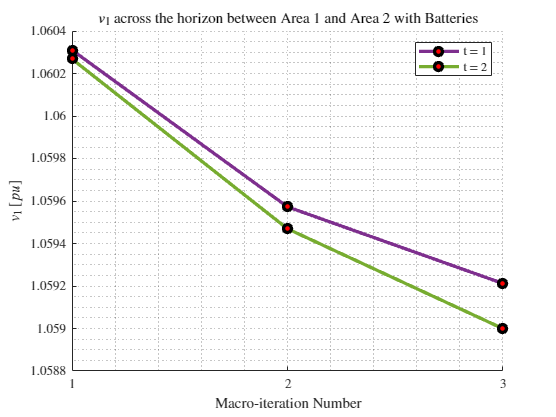

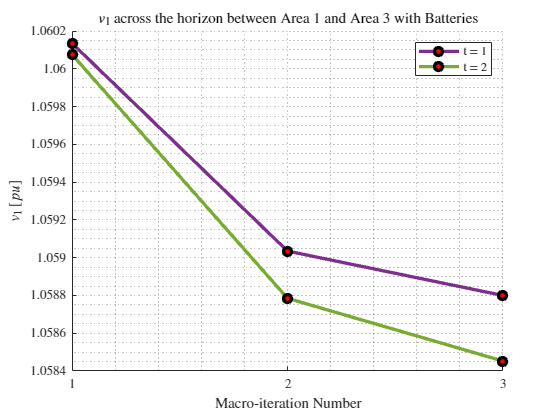

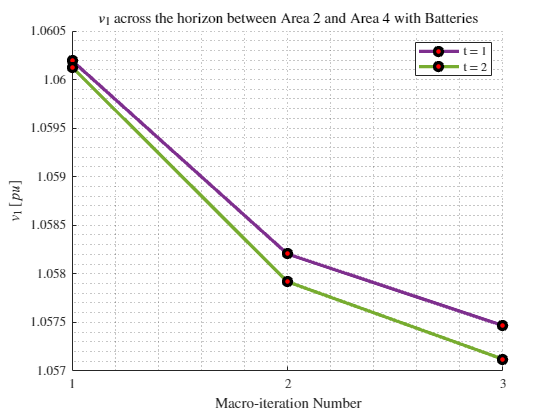

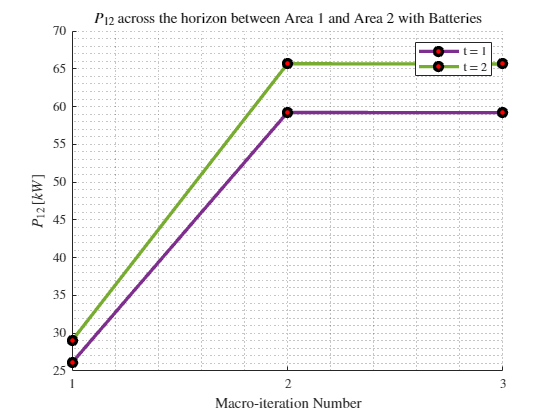

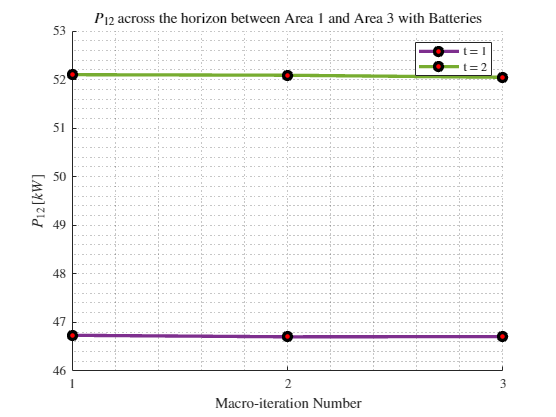

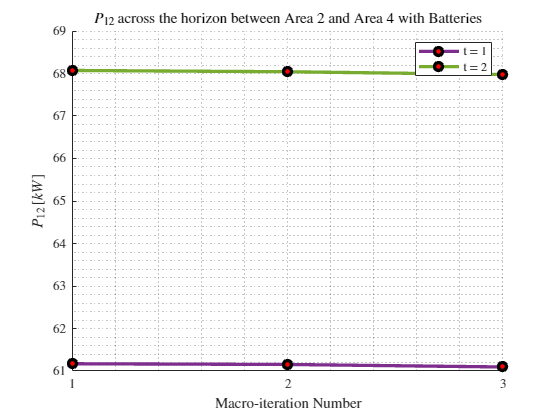

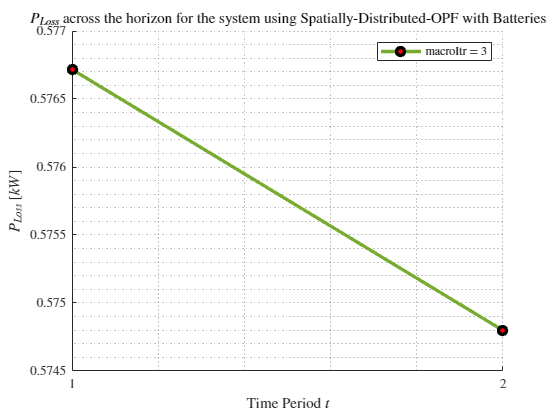

PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr(:, 1:macroItr+1);
PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr(1:macroItr+1);
v1_1toT_vs_macroItr = v1_1toT_vs_macroItr(:, :, 1:macroItr+1);
S12_1toT_vs_macroItr = S12_1toT_vs_macroItr(:, :, 1:macroItr+1);
P12_1toT_vs_macroItr = real(S12_1toT_vs_macroItr);
time_dist = time_dist(1:macroItr+1, :);

results = struct();
results.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
results.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
results.v1_1toT_vs_macroItr = v1_1toT_vs_macroItr;
results.S12_1toT_vs_macroItr = S12_1toT_vs_macroItr;

results.P12_1toT_vs_macroItr = P12_1toT_vs_macroItr;
% plot_relationships_over_time(results, simInfo, sysInfo)
plot_simulation_results(results, simInfo, sysInfo)

grandTotalTime = toc(start)

grandTotalTime = 351.4551

    
lineLoss_kW = 0;

for areaNum = 1:numAreas
    areaInfo = sysInfo.Area{areaNum};
    lineLoss_Area_kW = areaInfo.PLoss_allT * kVA_B;
    lineLoss_kW = lineLoss_kW + lineLoss_Area_kW;
end
area1Info = sysInfo.Area{1};

substationPower_kW = sum(area1Info.P_Area_1toT(1, :))*kVA_B;

maxTimes_vs_macroItr = max(time_dist, [], 2);
time_if_parallel = sum(maxTimes_vs_macroItr);
time_if_serial = sum(sum(time_dist));

if ~copf
    simNatureStringFull = strcat(simNatureString, " with ", num2str(numAreas), " Areas.");
else
    simNatureStringFull = simNatureString;
end

disp('------------------------------------------------------------')

------------------------------------------------------------


disp(['Machine ID: ', getenv("COMPUTERNAME")])

Machine ID: ETRL204-ARYAN


disp(['Horizon Duration: ', num2str(T)])

Horizon Duration: 2


disp(['Nature of Simulation: ', simNatureStringFull])

    "Nature of Simulation: "    "Spatially-Distributed-OPF with 4 Areas."



disp(['Line Loss: ', num2str(lineLoss_kW),' kW'])                       

Line Loss: 1.1515 kW


disp(['Substation Power: ', num2str(substationPower_kW),' kW'])

Substation Power: 76.5322 kW


disp(['Number of Macro-Iterations: ', num2str(macroItr)])

Number of Macro-Iterations: 2


disp(['Simulation Time: ', num2str(grandTotalTime), ' s'])

Simulation Time: 351.4551 s


disp(['Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s'])

Time to solve with sequential (non-parallel) computation: 342.233 s


disp(['Time to solve if OPF computation paralellized: ', num2str(time_if_parallel), ' s'])

Time to solve if OPF computation paralellized: 178.0379 s


disp('------------------------------------------------------------')

------------------------------------------------------------


% Assuming sysInfo, numAreas, T, and noBatteries are already defined in your workspace

% Construct the folder and file names
folderName = fullfile('processedData', sysInfo.systemName, strcat('numAreas_', num2str(numAreas), "/"));
prefixName = strcat(folderName, strcat('Horizon_', num2str(T)));
% systemSolutionName_x = strcat(prefixName, '_optimalSolutions.csv'); % For CSV file

% Determine the string based on whether batteries are included
if ~noBatteries
    battstring = 'withBatteries';
else
    battstring = 'withoutBatteries';
end

% Construct the full path for the TXT file
systemsSolutionName_fval = strcat(prefixName, "_", getenv('COMPUTERNAME'), '_results_', battstring, '.txt');

% Open the file for writing
fileID = fopen(systemsSolutionName_fval, 'w');

% Check if the file was opened successfully
if fileID == -1
    error('Failed to open file for writing.');
end

% Write the results to the file
fprintf(fileID, '------------------------------------------------------------\n');
fprintf(fileID, 'Machine ID: %s\n', getenv("COMPUTERNAME"));
fprintf(fileID, 'Horizon Duration: %d\n', T);
fprintf(fileID, 'Nature of Simulation: %s\n', simNatureStringFull);
fprintf(fileID, 'Line Loss: %.2f kW\n', lineLoss_kW);                       
fprintf(fileID, 'Substation Power: %.2f kW\n', substationPower_kW);
fprintf(fileID, 'Number of Macro-Iterations: %d\n', macroItr);
fprintf(fileID, 'Simulation Time: %.2f s\n', grandTotalTime);
fprintf(fileID, strcat('Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s'));

Time to solve with sequential (non-parallel) computation: 342.233 s


fprintf(fileID, 'Time to Solve if OPF computation parallelized: %.2f s\n', time_if_parallel);
fprintf(fileID, '------------------------------------------------------------\n');

% Close the file
fclose(fileID);

% Display a message indicating that the results were saved
disp(['Results saved to ', systemsSolutionName_fval]);

    "Results saved to "    "processedData\ieee123\numAreas_4\Horizon_2_ETRL204-ARYAN_results_withBatteries.txt"

